x=input('Enter the sequence : ');
N=input('Enter the Point    : ');
n=length(x);
x=[x zeros(1,N-n)];
y=bitrevorder(x);
M=log2(N);
for m=1:M
    d=2^m;
    for l=1:d:N-d+1
        for k=0:(d/2)-1
            w=exp(-1i*2*pi*k/d);
            z1=y(l+k);
            z2=y(l+k+d/2);
            y(l+k)=z1+w*z2;
            y(l+k+d/2)=z1-w*z2;
        end
    end
end
disp(y);

   1.0e+02 *

   1.2750 + 0.0000i   0.2432 + 0.8303i  -0.2550 + 0.5100i  -0.3932 + 0.2303i  -0.4250 + 0.0000i  -0.3932 - 0.2303i  -0.2550 - 0.5100i   0.2432 - 0.8303i



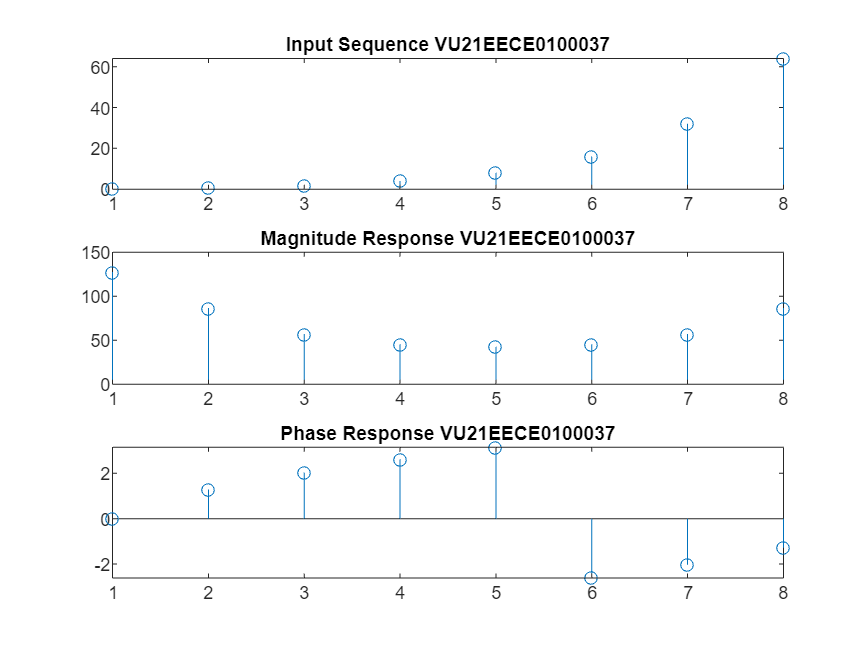


subplot(3,1,1)
stem(abs(x));
title('Input Sequence VU21EECE0100037');
subplot(3,1,2)
stem(abs(y));
title('Magnitude Response VU21EECE0100037');
subplot(3,1,3)
stem(angle(y));
title('Phase Response VU21EECE0100037');